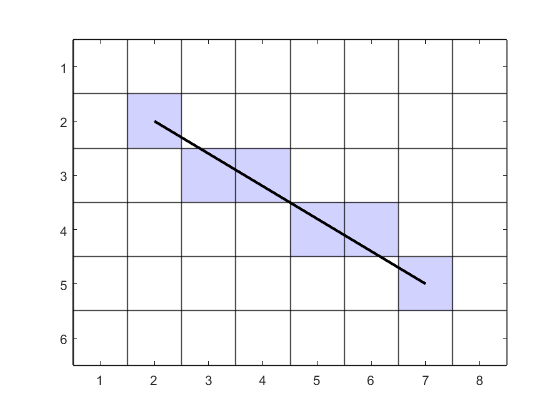

clear

% Raster parameters
Nx = 8;
Ny = 6;

% Line coordinates and colour
x0 = 2;
y0 = 2;
x1 = 7;
y1 = 5;
blue = [210, 210, 255];
green = [230, 255, 230];

% Initialise raster array and calculate pixel co-ordinates
img = uint8(255 * ones(Ny, Nx, 3));

img(2,2,:) = blue;
img(3,3,:) = blue;
img(3,4,:) = blue;
img(4,5,:) = blue;
img(4,6,:) = blue;
img(5,7,:) = blue;

image(img)
hold on
for row = 1 : 1 : Nx
    xline(row-0.5, Color='k', LineWidth=1)
    yline(row-0.5, Color='k', LineWidth=1)
end
plot([x0, x1], [y0, y1], 'k', LineWidth=2)
hold off


xticks(1:Nx)
axis equal
axis([0.5, Nx+0.5, 0.5, Ny+0.5])
exportgraphics(gcf,'../images/bresenham_example_1_4.png','Resolution',300) 